 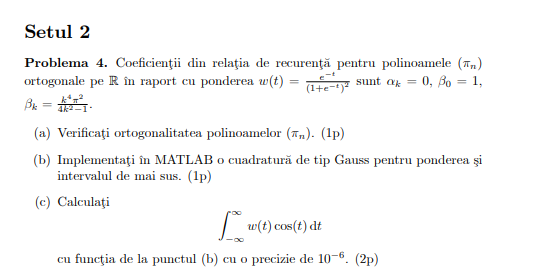

clear;
close all;
clc;
%a)

Pentru a verifica ortogonalitatea polinoamelor $\(\pi_n\)$ în raport cu ponderea $\( w(t) = \frac{e^{-t}}{(1+e^{-t})^2} \)$, trebuie să demonstrăm că integrala produsului dintre două polinoame distincte $ \(\pi_m(t)\)$ și $\(\pi_n(t)\)$ înmulțite cu ponderea $\( w(t) \)$ pe intervalul de definiție este zero.


$$\( \int_{-\infty}^{\infty} \pi_m(t) \pi_n(t) w(t) \, dt = 0 \) pentru \( m \neq n \)$$


Polinoamele $\(\pi_n\)$ sunt ortogonale pe $\(\mathbb{R}\)$ în raport cu ponderea $ \( w(t) = \frac{e^{-t}}{(1+e^{-t})^2} \)$. 


$$\[ \int_{-\infty}^{\infty} \pi_m(t) \pi_n(t) w(t) \, dt = 0 \quad \text{pentru} \quad m \neq n \]$$


Aici, $\( w(t) = \frac{e^{-t}}{(1+e^{-t})^2} \)$.

Deci formla pe care trebuie sa o demonstram este:

$\[ \int_{-\infty}^{\infty} \pi_m(t) \pi_n(t) \frac{e^{-t}}{(1+e^{-t})^2} \, dt \]$=0

Din teorie, se stie faptul ca


$$\pi_{-1} \left(t\right)=0$$



$$\pi_1 \left(t\right)=1$$


Si relatia de recurenta este: 


$$\pi_{k+1} \left(t\right)=t*\pi_k \left(t\right)-\beta_k *\pi_{k-1} \left(t\right)$$


In continuare, in rezolvarea va fi facuta in matlab

 syms t

Ponderea va fi (in functie de t)

 w=exp(-t)/((1+exp(-t))^2) 

 Astfel primele polinoame vor fi:

 pi1=simplifyFraction(calculeaza_polinom(1,t))
 pi2=simplifyFraction(calculeaza_polinom(2,t))
 pi3=simplifyFraction(calculeaza_polinom(3,t))
 pi4=simplifyFraction(calculeaza_polinom(4,t))
 pi5=simplifyFraction(calculeaza_polinom(5,t))

 Pentru a verifica ortogonalitatea, pentru 2 polinoame fixate (ex $\pi_2$si $\pi_3$):

vpa(int(pi2*pi3*w,t,-Inf,Inf))

Care este 0.

Similar se face pentru orice $n\not= m$

n=4; 
for i=1:n
     for j=1:n
         if i~=j
             pii=simplifyFraction(calculeaza_polinom(i,t));
             pij=simplifyFraction(calculeaza_polinom(j,t));
             valoare_integrala=vpa(int(pi2*pi3*w,t,-Inf,Inf));
         end
     end
 end

%b)
n=5;

$\alpha_k$vor fi urmatoarele (pentru n=5):

alpha_k=zeros(1, 5)

$\beta_k$vor fi urmatoarele (pentru n=5):

k = (1:4);
beta_k=(k.^4.*pi.^2)./(4.*k.^2.-1);
beta_k=[1,beta_k]

Noduriile si coeficientii cuadraturii vor fi (pentr n=5):

[noduri,coeficienti]=Gaussquad(alpha_k,beta_k)

 Pentru subpunctul c) prima data calculam integrala in matlab, pentru a avea o solutie aproximativa. Acest lucru ajuta pentru a valida ulterior solutia

%c)
syms t
valoare_integrala_matlab=vpa(int(exp(-t)./((1.+exp(-t)).^2).*cos(t),t,sym(-Inf),sym(Inf)))

format longg
f=@(x) cos(x);
eroare=1e-6;
ultima_valoare_calculata=0;
for n=2:50
    alpha_k=zeros(1, n);
    k = (1:n-1);
    beta_k=(k.^4.*pi.^2)./(4.*k.^2.-1);
    beta_k=[1,beta_k];
    [noduri,coeficienti]=Gaussquad(alpha_k,beta_k);
    valoare_functie=vquad(noduri,coeficienti,f);
    if abs(valoare_functie-ultima_valoare_calculata) < eroare && n~=2
        fprintf('Valoarea integralei este %2d', valoare_functie);
        fprintf('Convergenta obtinuta pentru %d noduri', n);
        break;
    end
    ultima_valoare_calculata=valoare_functie;
end

 Ultimul pas este cel de verificare. Pentru a ne verifica se va folosi rezultatul functiei din matlab (se face o diferenta absoluta, care ar trebui sa fie mai mica decat eroarea setata)

diferenta = abs(valoare_functie-valoare_integrala_matlab)
logical(diferenta <= eroare) 

Functie care calculeaza polinoamele ortogonale pentru a)

 function pin=calculeaza_polinom(n,t)
    alpha_k=zeros(1, n);
    k = (1:n-1);
    beta_k=(k.^4.*pi.^2)./(4.*k.^2.-1);
    beta_k=[1,beta_k];
    pi_last=1;
    pi_last_last=0;
    for i=1:n
        pin=t*pi_last-beta_k(i)*pi_last_last;
        pi_last_last=pi_last;
        pi_last=pin;
    end
 end

 Functie care calculeaza noduriile si coeficientii in functie de valoriile lui alpha si a lui beta. Acest lucru este util deoarece in problema data este dat deja alpha_k si beta_k.

function [g_nodes,g_coeff]=Gaussquad(alpha,beta)
%GAUSSQUAD - generate Gaussian quadrature formula
%computes nodes and coefficients for 
%Gauss rules given alpha and beta
%method - Jacobi matrix
n=length(alpha); rb=sqrt(beta(2:n));
J=diag(alpha)+diag(rb,-1)+diag(rb,1);
[v,d]=eig(J);
g_nodes=diag(d); 
g_coeff=beta(1)*v(1,:).^2;
end

 Aceasta functie aproximeaza valoarea integralei in functie de noduriile si coeficientii calculati (in functia definita anterior).

function I=vquad(g_nodes,g_coeff,f)
I=g_coeff*f(g_nodes);
end

